## Problema 1

### Calculul coeficientilor spline-ului

Type = 0 $\Rightarrow$ Spline complet

Type = 1 $\Rightarrow$ Spline care utilizeaza derivatele secundare

Type = 2 $\Rightarrow$ Spline cubice naturale

Type = 3 $\Rightarrow$ Spline deBoor

## Problema 2

f=@(x) cos(x);

x=[0,pi/6,pi/4,pi/3,pi/2,pi];
y=f(x);
d=-sin([0,pi]);
t=linspace(0,pi,200)';

### Spline complete

c0=CubicSpline(x,y,0,d);
z0=evalspline(x,c0,t);

### Spline D2

d2 = -cos([0,pi]);
c1=CubicSpline(x,y,1,d2);
z1=evalspline(x,c1,t);

### Spline naturale

c2=CubicSpline(x,y,2);
z2=evalspline(x,c2,t);

### Spline deBoor

c3=CubicSpline(x,y,3);
z3=evalspline(x,c3,t);

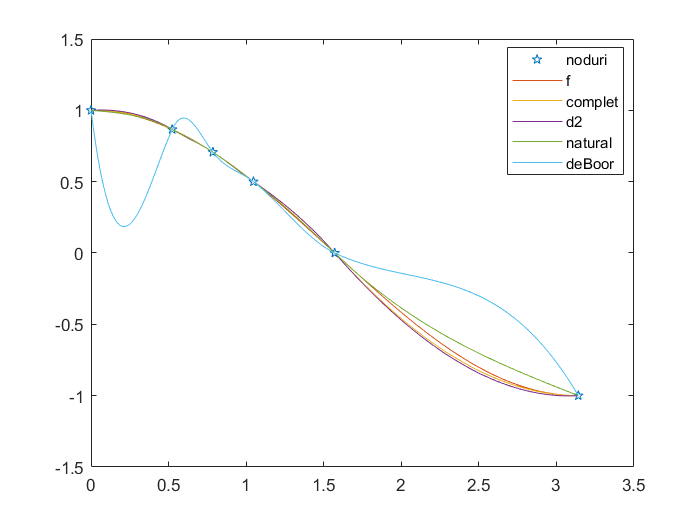

yg=f(t);
plot(x,y,'pentagram',t,[yg,z0,z1,z2,z3])
legend('noduri','f','complet','d2','natural','deBoor','Location','Best')

## Problema 3

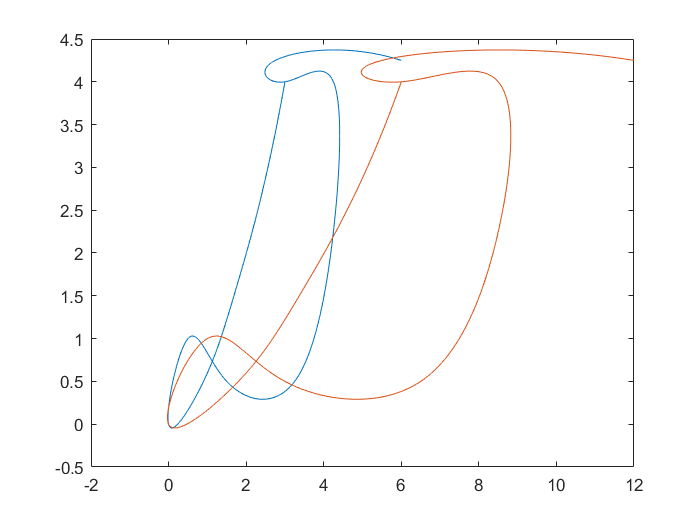

t=0:11;
x=[3,1.75,0.9,0,0.5,1.5,3.25,4.25,4.25,3,2.75,6.0];
y=[4,1.6,0.5,0,1.0,0.5,0.5,2.25,4.0,4,4.25,4.25];
cx=CubicSpline(t,x,2);
cy=CubicSpline(t,y,3);
vals = linspace(0,11,2000)';
x_vals = evalspline(t,cx,vals);
y_vals = evalspline(t,cy,vals);
plot(x_vals,y_vals, 2*x_vals, y_vals);

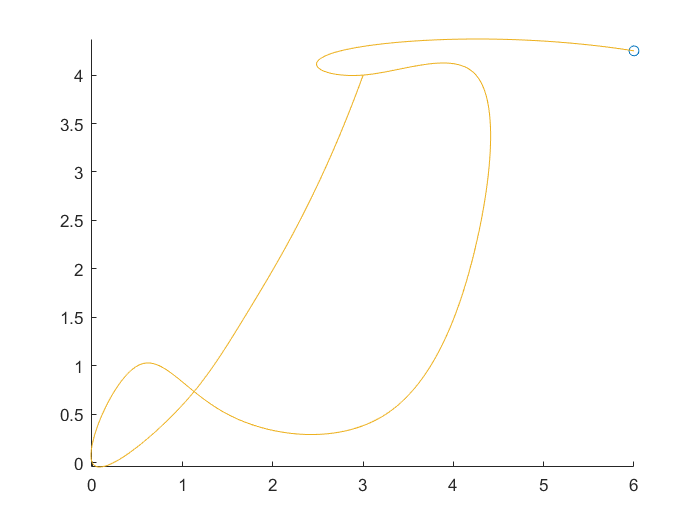

comet(x_vals,y_vals);

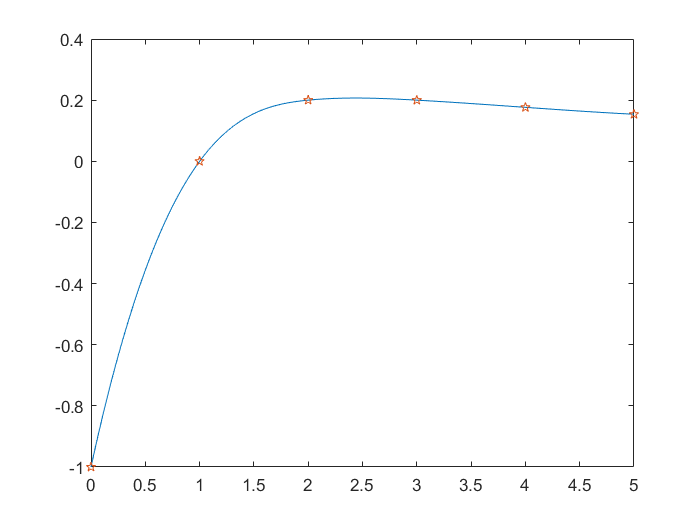

x = 0:5;
f=(x-1)./(x.^2+1);
t=linspace(0,5,200);
z=spline(x,f,t);
plot(t,z,x,f,'pentagram')

pp=spline(x,f)

pp = struct with fields:
      form: 'pp'
    breaks: [0 1 2 3 4 5]
     coefs: [5×4 double]
    pieces: 5
     order: 4
       dim: 1


pp.coefs

ans =     0.1171   -0.7514    1.6343   -1.0000
    0.1171   -0.4000    0.4829         0
    0.0143   -0.0486    0.0343    0.2000
    0.0020   -0.0056   -0.0199    0.2000
    0.0020    0.0005   -0.0251    0.1765


z2=ppval(pp,t);

function c = CubicSpline(x,f,type,der)
    if (nargin < 4) || (type==2), der=[0,0]; end
    
    n = length(x);
    if any(diff(x)<0),[x,ind]=sort(x); else ind=1:n; end
    
    y=f(ind); x=x(:); y=y(:);
    dx=diff(x);
    ddiv=diff(y)./dx;
    ds=dx(1:end-1); dd=dx(2:end);
    dp=2*(ds+dd);
    md=3*(dd.*ddiv(1:end-1)+ds.*ddiv(2:end));

    switch type
        case 0
            dp1=1;dpn=1;vd1=0;vdn=0;
            md1=der(1); mdn=der(2);
        case {1,2}
            dp1=2;dpn=2;vd1=1;vdn=1;
            md1=3*ddiv(1)-0.5*dx(1)*der(1);
            mdn = 3*ddiv(end)+0.5*dx(end)*der(2);
        case 3
            x31=x(3)-x(1); xn=x(n)-x(n-2); 
            dp1 = dx(2); dpn=dx(end-1);
            vd1 = x31;
            vdn = xn;
            md1=((dx(1) +2*x31)*dx(2)*ddiv(1)+dx(1)^2*ddiv(2))/x31;
            mdn=(dx(end)^2*ddiv(end-1)+(2*xn+dx(end))*dx(end-1)*ddiv(end))/xn;
    end

    dp=[dp1;dp;dpn];
    dp1=[0;vd1;dd];
    dm1=[ds;vdn;0];
    md=[md1;md;mdn];
    A=spdiags([dm1,dp,dp1],-1:1,n,n);
    m=A\md;
    c(:,4)=y(1:end-1);
    c(:,3)=m(1:end-1);
    c(:,1)=(m(2:end)+m(1:end-1)-2*ddiv)./(dx.^2);
    c(:,2)=(ddiv-m(1:end-1))./dx-dx.*c(:,1);
end

function z=evalspline(x,c,t)
    n=length(x);
    x=x(:); t=t(:);
    k=ones(size(t));
    for j=2:n-1
       k(x(j) <= t) = j; 
    end
    s = t-x(k);
    z=c(k,4) + s.*(c(k,3) + s.*(c(k,2) + s.*c(k,1)));
end